# **Adjustment for Non_Linear GH  **

%Unknown X, Residual
addpath Template_data\
addpath Function\
clearvars

**1. Input Data(Copy here only)**

addpath Semester_2nd_data\

Elist=["Free_=||"
    "Free_data=[]"
    "L_=|Ext('9series2.txt','x','1st')|Ext('9series2.txt','y','2st')|"
    "L_data=[Ext('9series2.txt','x','1st');Ext('9series2.txt','y','2st')]"
    "X_=|rx ry radius|"
    "X_data=[3;0.3;1]"];
AnalyzeEList(Elist)

VCE_CONFIG=false;
[Var_ind,Var_name]=findVar()

Var_ind = 1×2 cell array
    {12×1 double}    {12×1 double}


Var_name = 2×1 string array
    "x"
    "y"


S_L=expand_V(ones(size(L_)),Var_ind, u2u("1m 1m"));  

F_ =[(y-ry).^2+(x-rx).^2-radius^2]; 
 

**2. Setup your Output and Threshold**

VCE_CONFIG=false; %Variance Component Estimation
epsilon = 10^-9; %Convergence
delta = 1e-12; %Convergence
L_Config=false;  %display output for L
SLL_Config=false; %display output for S
Func_Config=true; %display output for Function Model
Cons_Config=true; %display output for Constrint
A_Config=false; %display output for Design Matrix
Obs_Config=true; %display output for Observation


## **1. Gaussian **Helmert  Model

**Preprocess**


checkConfig();

The angle in L_. 
No angle Detected
The angle in X_. 
No angle Detected


if ~isempty(L_i)
    F_m(L_i)=mod(F_(L_i));
else
    F_m=F_;
end

%Number of observations
no_n =  length(F_);
%Number of unknowns
no_u = length(X_);
%Redundancy
redundancy = no_n-no_u;

**Function and Observation**

if ~exist("dash")
    dash=[0];
end
L_dash_=L_+dash;
F_=F_+dash;   
F_m=F_m+dash;

if L_Config
    disp("=========================")
    disp("1. Observation Vector (Observation)") 
    disp("=========================")
    L_==L_data+dash    %Show here
end

**Stochastic Model**


sigma_0 =1;
if ~exist("S_LL")
    S_LL = diag(S_L.^2);     %Show here
end
if ~exist("S_L")
    S_L = diag(S_LL);       %Show here
end

Q_LL = 1/sigma_0^2*S_LL;
P_LL = inv(Q_LL); 

if SLL_Config
    disp("=========================")
    disp("2. Stochastic Model (SLL/P)") 
    disp("=========================")
    diag(L_.^2)  %Show here
end

**Constraint**

if exist("cons_info","var")

    B_=cons_info{1};
    if ~isempty(cons_info{2})
        FB_=cons_info{2};
    end
       %Show Here
    no_b=size(B_);
    no_b=no_b(1);
    redundancy = no_n-no_u+no_b;
end
if Cons_Config 
    if exist("cons_info","var")
        disp("=========================")
        disp("3.Constraint Model (Constraint Model)") 
        disp("=========================")
        display(cons_info{4})
        Cons_model=FB_==LB_data    %Show Here
        B_
    end
end

**Function Model**

if Func_Config
    disp("=========================")
    disp("3.Function Model (Redundancy, Function)") 
    disp("=========================")
    0==F_   %Show Here
    redundancy  %Show Here
end

3.Function Model (Redundancy, Function)


$$ans = \left(\begin{array}{c} 0={\left(\mathrm{rx}-x_{1}\right)}^{2}+{\left(\mathrm{ry}-y_{1}\right)}^{2}-{\mathrm{radius}}^{2}\\ 0={\left(\mathrm{rx}-x_{2}\right)}^{2}+{\left(\mathrm{ry}-y_{2}\right)}^{2}-{\mathrm{radius}}^{2}\\ 0={\left(\mathrm{rx}-x_{3}\right)}^{2}+{\left(\mathrm{ry}-y_{3}\right)}^{2}-{\mathrm{radius}}^{2}\\ 0={\left(\mathrm{rx}-x_{4}\right)}^{2}+{\left(\mathrm{ry}-y_{4}\right)}^{2}-{\mathrm{radius}}^{2}\\ 0={\left(\mathrm{rx}-x_{5}\right)}^{2}+{\left(\mathrm{ry}-y_{5}\right)}^{2}-{\mathrm{radius}}^{2}\\ 0={\left(\mathrm{rx}-x_{6}\right)}^{2}+{\left(\mathrm{ry}-y_{6}\right)}^{2}-{\mathrm{radius}}^{2}\\ 0={\left(\mathrm{rx}-x_{7}\right)}^{2}+{\left(\mathrm{ry}-y_{7}\right)}^{2}-{\mathrm{radius}}^{2}\\ 0={\left(\mathrm{rx}-x_{8}\right)}^{2}+{\left(\mathrm{ry}-y_{8}\right)}^{2}-{\mathrm{radius}}^{2}\\ 0={\left(\mathrm{rx}-x_{9}\right)}^{2}+{\left(\mathrm{ry}-y_{9}\right)}^{2}-{\mathrm{radius}}^{2}\\ 0={\left(\mathrm{rx}-x_{10}\right)}^{2}+{\left(\mathrm{ry}-y_{10}\right)}^{2}-{\mathrm{radius}}^{2}\\ 0={\left(\mathrm{rx}-x_{11}\right)}^{2}+{\left(\mathrm{ry}-y_{11}\right)}^{2}-{\mathrm{radius}}^{2}\\ 0={\left(\mathrm{rx}-x_{12}\right)}^{2}+{\left(\mathrm{ry}-y_{12}\right)}^{2}-{\mathrm{radius}}^{2} \end{array}\right)$$

redundancy =      9


**Observation Equation**

 
% Observation Equation

syms V_ [length(L_),1];
Ndeal(L_,V_+L_)
psi_=eval(F_);
J1_=jacobian(psi_,X_);  %Show Here
J2_=jacobian(psi_,L_);

if A_Config
    disp("=========================")
    disp("4.Observation Equation(Design Matrix, Objective)") 
    disp("=========================")
    J1_
    J2_

end
if Obs_Config
    disp("=========================")
    disp("5.Observation Equation(Objective)") 
    disp("=========================")
    disp("O=vTPv--->min")   %Show Here
    psi_==0
end

5.Observation Equation(Objective)


O=vTPv--->min


$$ans = \left(\begin{array}{c} {\left(V_{1}-\mathrm{rx}+x_{1}\right)}^{2}+{\left(V_{13}-\mathrm{ry}+y_{1}\right)}^{2}-{\mathrm{radius}}^{2}=0\\ {\left(V_{2}-\mathrm{rx}+x_{2}\right)}^{2}+{\left(V_{14}-\mathrm{ry}+y_{2}\right)}^{2}-{\mathrm{radius}}^{2}=0\\ {\left(V_{3}-\mathrm{rx}+x_{3}\right)}^{2}+{\left(V_{15}-\mathrm{ry}+y_{3}\right)}^{2}-{\mathrm{radius}}^{2}=0\\ {\left(V_{4}-\mathrm{rx}+x_{4}\right)}^{2}+{\left(V_{16}-\mathrm{ry}+y_{4}\right)}^{2}-{\mathrm{radius}}^{2}=0\\ {\left(V_{5}-\mathrm{rx}+x_{5}\right)}^{2}+{\left(V_{17}-\mathrm{ry}+y_{5}\right)}^{2}-{\mathrm{radius}}^{2}=0\\ {\left(V_{6}-\mathrm{rx}+x_{6}\right)}^{2}+{\left(V_{18}-\mathrm{ry}+y_{6}\right)}^{2}-{\mathrm{radius}}^{2}=0\\ {\left(V_{7}-\mathrm{rx}+x_{7}\right)}^{2}+{\left(V_{19}-\mathrm{ry}+y_{7}\right)}^{2}-{\mathrm{radius}}^{2}=0\\ {\left(V_{8}-\mathrm{rx}+x_{8}\right)}^{2}+{\left(V_{20}-\mathrm{ry}+y_{8}\right)}^{2}-{\mathrm{radius}}^{2}=0\\ {\left(V_{9}-\mathrm{rx}+x_{9}\right)}^{2}+{\left(V_{21}-\mathrm{ry}+y_{9}\right)}^{2}-{\mathrm{radius}}^{2}=0\\ {\left(V_{10}-\mathrm{rx}+x_{10}\right)}^{2}+{\left(V_{22}-\mathrm{ry}+y_{10}\right)}^{2}-{\mathrm{radius}}^{2}=0\\ {\left(V_{11}-\mathrm{rx}+x_{11}\right)}^{2}+{\left(V_{23}-\mathrm{ry}+y_{11}\right)}^{2}-{\mathrm{radius}}^{2}=0\\ {\left(V_{12}-\mathrm{rx}+x_{12}\right)}^{2}+{\left(V_{24}-\mathrm{ry}+y_{12}\right)}^{2}-{\mathrm{radius}}^{2}=0 \end{array}\right)$$

**Input Data**

% 6.Measurement L
Ndeal(L_, L_data)
% 7.Free Error X
Ndeal(Free_, Free_data)
% 8.Initial values for the unknowns
Ndeal(X_, X_data)
% 8.Initial values for the V
Ndeal(V_, zeros(size(V_)))

if exist("LB_","var"),Ndeal(LB_, LB_data); end
if exist("X_O","var"),Ndeal(X_O, X_data); end 

## **2. Adjustment**

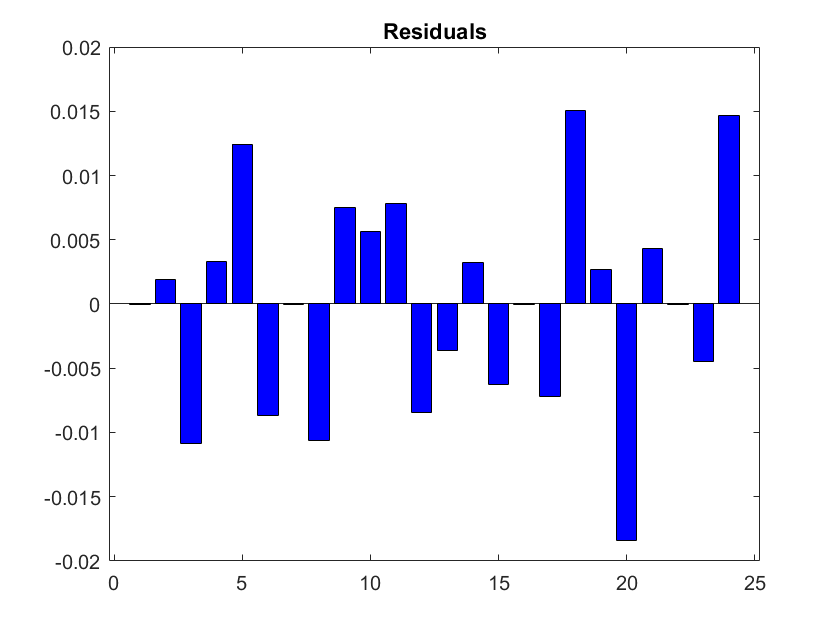

 
L_0=eval(L_);
V_0=eval(V_);
L_dash_0=eval(L_dash_);
X_0=eval(X_);
L_dash_hat=eval(L_dash_);
V_hat=eval(V_);
%break-off conditions

iteration = 0;
max_psi=10^Inf;
syms thx
safe=thx;
thx=0;
checkVCE=true;
vce_iter=0;

if VCE_CONFIG==true
% initial values
    a_all=expand_V(zeros(size(L_)),Var_ind,1*ones(length(Var_ind),1));
    s_o_all=expand_V(zeros(size(L_)),Var_ind,10^10*ones(length(Var_ind),1));
end
%VCE
while checkVCE
    vce_iter=vce_iter+1;
    
    if VCE_CONFIG==true
        %Iteration 1
        checkVCE=sum(abs(s_o_all-1)>10^-4)~=0;
        %VC Matrix of the observations
        C_LL_all=diag(a_all.^2.*S_L.^2);
        %Cofactor matrix of the observations
        Q_LL=1/sigma_0^2*C_LL_all;
        P_LL = inv(Q_LL); 
    else
        checkVCE=0;
    end
    
    %break-off conditions    
    max_psi=10^Inf;
    while  max_psi>epsilon || max(abs(eval(F_m)))>delta


        Ndeal(L_,L_0); 
        iteration=iteration+1;
        
        J1_evl=eval(J1_+safe);
        J2_evl=eval(J2_+safe);
        psi_evl=eval(psi_);
 
        c_evl=0;
        w1_evl=-J2_evl*V_hat+psi_evl-c_evl;
                
        
        if exist("cons_info","var")
            if exist("cons_info") 
                FB_evl=eval(FB_);
                B_evl=eval(B_+safe);  
                w2_evl=FB_evl-eval(LB_data+safe);
                n_ext = [J1_evl'*inv(J2_evl*Q_LL*J2_evl')*w1_evl;-w2_evl];
            else
                error("flag is not right")
        
            end
            
            N_ext = [-J1_evl'*inv(J2_evl*Q_LL*J2_evl')*J1_evl B_evl'; B_evl 0];
            Q_xx_ext = inv(N_ext);
            %n_ext = [n;zeros(no_b,1)];
            
            %Inversion of normal matrix / Cofactor matrix of the unknowns
            
            Q_XX = Q_xx_ext(1:no_u,1:no_u);    
            %Solution of normal equation
            X_smallhat=Q_xx_ext*n_ext;  
            k1 = inv(J2_evl*Q_LL*J2_evl')*(-J1_evl*X_smallhat(1:end-1)-w1_evl);
            k2=X_smallhat(end);
            V_hat = Q_LL*J2_evl'*k1;
            Ndeal(V_,V_hat);
            Ndeal(X_,X_smallhat(1:no_u)+eval(X_));
            
 
        else
            %Vector of right hand side of normal equations
            
            N = J2_evl*Q_LL*J2_evl'; 
            n_ext =  [-w1_evl ; zeros(no_u,1)];
            N_ext=[N J1_evl; J1_evl' zeros(no_u,no_u)]; 
            Q_xx_ext = inv(N_ext);
            X_smallhat=Q_xx_ext*n_ext;  
            V_hat = Q_LL*J2_evl'*X_smallhat(1:no_n);
            Ndeal(V_,V_hat);
            Ndeal(X_,X_smallhat(end-no_u+1:end)+eval(X_));
        end
        

        max_psi=max(abs(psi_evl));
        V_hat_rad=V_hat;
        % Update v

        L_dash_hat = L_dash_0+V_hat;
        L_hat=L_0+V_hat;
        X_hat=eval(X_);
        Ndeal(X_O,X_hat);
        %Objective function
        vTPv = V_hat'*P_LL*V_hat;
    
        if iteration > 100
            error("Wrong")
        elseif vce_iter > 20
            error("Wrong VCE")
        end
        Ndeal(L_,L_0+V_hat);
    end
    
    %Empirical reference standard deviation
    s_0 = sqrt(vTPv/(redundancy));     %a posteriori
    
    if exist("cons_info","var")
        %VC matrix of adjusted unknowns
        S_XX_hat = -s_0^2*Q_xx_ext(1:no_u,1:no_u);
        %Cofactor matrix of adjusted observations
        Q_vv = Q_LL*J2_evl'*inv(J2_evl*Q_LL*J2_evl')*J2_evl*Q_LL;
    else
        %VC matrix of adjusted unknowns
        S_XX_hat = -s_0^2*Q_xx_ext(end-no_u+1:end,end-no_u+1:end);
        %Cofactor matrix of the residuals
        Q_vv = Q_LL*J2_evl'*Q_xx_ext(1:no_n,1:no_n)*J2_evl*Q_LL;
    end
    Q_LL_hat = Q_LL-Q_vv;
    S_LL_hat = s_0^2*Q_LL_hat;
    S_vv = s_0^2*Q_vv; 
    S_v=sqrt(diag(S_vv));
    S_X=sqrt(diag(S_XX_hat));
    S_L_hat=sqrt(diag(S_LL_hat));
    

    %Check VCE 
    Q_vvP = Q_vv*P_LL;
    if VCE_CONFIG==true       %~exist("Var_ind")
        %[Var_ind,Var_name]=findVar();

        for i =1:length(Var_ind)
            P_dist=P_LL(Var_ind{i},Var_ind{i});
            Q_vvP_dist=Q_vvP(Var_ind{i},Var_ind{i});
            %Sub-vectors of residuals
            v_dist = V_hat_rad(Var_ind{i},1);          %sub-vector of v
            %Compute trace for sub-matrices Q_vvP_dist and Q_vvP_dir
            r_dist = trace(Q_vvP_dist);
            s_o_dist(i,1) =sqrt((v_dist'*P_dist*v_dist)/r_dist);
        end
 
        s_o_all=expand_V(zeros(size(L_)),Var_ind,s_o_dist);
        a_all=a_all.*s_o_all;
    end

end
  
%plotxyc(X,L_dash,eval(F_))
figure
bar(V_hat,"b")
title("Residuals")


%Final check
if max(abs(eval(F_m)))<delta
    disp("Good")
else
    disp("Wrong")
end

Good


if exist("list_info") && length(list_info)==3
            [X_hat,useless]=normalizeX_(X_hat,"inverse",list_info);
            [X_0,useless]=normalizeX_(X_0,"inverse",list_info);
            Ndeal(X_,X_hat);
end
if exist("rescale_L1") 
            [L_hat,useless]=normalizeX_(L_hat,"inverse",rescale_L1);
            [L_0,useless]=normalizeX_(L_0,"inverse",rescale_L1);
            Ndeal(L_,L_hat);
end
if exist("cons_info",'var')
    rank_deficient=size(N);
    rank_deficient=rank_deficient(1)-rank(N)
    LB_data-eval(FB_)
end

**Get X, L, and residual.**

%Conversion
if exist("X_i",'var')
    X_hat(X_i)=mod(X_hat(X_i)*200/pi,400);
    S_X(X_i)=S_X(X_i)*200/pi;
end    
if exist("L_i",'var')
    L_0(L_i)=L_0(L_i)*200/pi;
    L_dash_hat(L_i)=mod(L_dash_hat(L_i)*200/pi,400);
    L_hat(L_i)=mod(L_hat(L_i)*200/pi,400);
    S_L_hat(L_i)=S_L_hat(L_i)*200/pi;
    V_hat(L_i)=V_hat(L_i)*200/pi;
    S_v(L_i)=S_v(L_i)*200/pi;
end

disp("=========================")

disp("6.Get Result and S_xx") 

6.Get Result and S_xx


disp("=========================")

format long


disp("Get Unknown X_hat, S_x:") 

Get Unknown X_hat, S_x:


Unknown=arrayfun(@(x) sprintf("%s",x),X_);
table(Unknown,X_0,X_hat,S_X)

ans = 3×4 table
    Unknown     X_0          X_hat                  S_X        
    ________    ___    _________________    ___________________

    "rx"          3     70.0004775208078    0.00550132060723987
    "ry"        0.3     99.9975425084154     0.0055011642749189
    "radius"      1    -40.0018217694265    0.00388996583033688



disp("Get Updated L_hat, S_l:") 

Get Updated L_hat, S_l:


Measurment=arrayfun(@(x) sprintf("%s",x),L_);
table(Measurment,L_0,L_hat,L_dash_hat,S_L_hat,["V_"+(1:length(V_hat))'],V_hat,S_v)

ans = 24×8 table
    Measurment      L_0           L_hat             L_dash_hat             S_L_hat           Var6             V_hat                    S_v         
    __________    _______    ________________    ________________    ___________________    ______    _____________________    ____________________

      "x1"         70.019    70.0189983146798    70.0189983146798     0.0134752358038319    "V_1"     -1.68532016256887e-06    5.40312375928378e-06
      "x2"         89.982     89.983870861277     89.983870861277     0.0121489085646375    "V_2"       0.00187086127698218     0.00582975384134675
      "x3"        104.652    104.641170163905    104.641170163905    0.00891385902059161    "V_3"       -0.01082983609

**Get VCE Result**

if VCE_CONFIG==false       %~exist("Var_ind")
    [Var_ind,Var_name]=findVar();

    for i =1:length(Var_ind)
        P_dist=P_LL(Var_ind{i},Var_ind{i});
        Q_vvP_dist=Q_vvP(Var_ind{i},Var_ind{i});
        %Sub-vectors of residuals
        v_dist = V_hat_rad(Var_ind{i},1);          %sub-vector of v
        %Compute trace for sub-matrices Q_vvP_dist and Q_vvP_dir
        r_dist = trace(Q_vvP_dist);
        s_o_dist(i,1) =sqrt((v_dist'*P_dist*v_dist)/r_dist);
    end

    s_o_all=expand_V(zeros(size(L_)),Var_ind,s_o_dist);
    a_all=expand_V(zeros(size(L_)),Var_ind,1*ones(length(Var_ind),1));
    a_all=a_all.*s_o_all;
    
end
    

try
    disp("Variance Component") 
    a_all_dist=unique(a_all);
    table(Var_name,s_o_dist,a_all_dist) 
catch

    table(Measurment,s_o_all,a_all) 
end

Variance Component


ans = 2×3 table
    Var_name        s_o_dist            a_all_dist    
    ________    _________________    _________________

      "x"       0.012429099866857    0.012429099866857
      "y"       0.014445753140968    0.014445753140968


## **3. Quality Assessment**

**Global test**

disp("Global test") 

Global test


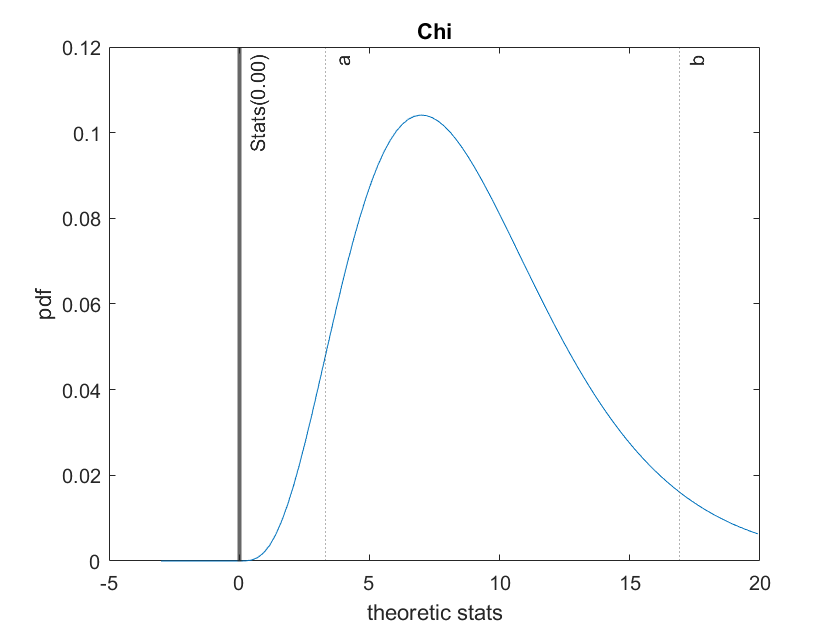

Test Statistic: 0.00 ,Critical value=[3.33,16.92]
1.Reject the null hypothesis H0: Same
1.Reject HC: Significant bigger with S=95.00%
2.Choose hypothesis HA: Significant Smaller with S=95.00%
2,Choose hypothesis HB: Significant difference with S=90.00%


confidence_tool=confidence_tool();
stats=confidence_tool.statistic_test_chi(0.95, sigma_0, s_0, redundancy);




disp("Internal and external reliability parameters") 

Internal and external reliability parameters



%Check 3σ rule
mat=sqrt(S_L_hat);  

%Compute EV
r_i=diag(Q_vv*P_LL);
EV=r_i*100;

% NV
sigma_v=sigma_0*sqrt(diag(Q_vv));
NV=abs(V_hat_rad)./sigma_v;


for j=1:size(mat)
    % 3 sigma update
    if V_hat_rad(j)>(3*mat(j)) || V_hat_rad(j)<(-3*mat(j))
        sigma3_rule(j,1)="exceed 3sigma";
    else
        sigma3_rule(j,1)="Good";
    end
    % EV update
    if EV(j)<1
        EV_comment(j,1)="not controlled";
    elseif EV(j)<10
        EV_comment(j,1)="poorly controlled";
    elseif EV(j)<30
        EV_comment(j,1)="sufficiently controlled";
    elseif EV(j)<70
        EV_comment(j,1)="good controlled";   
    else
        EV_comment(j,1)="Excellent";   
    end
    
    % NV
    if NV(j)<2.5
        NV_comment(j,1)="no blunder";
    elseif NV(j)<4
        NV_comment(j,1)="blunder possible";
        blunder=true;
    else
        NV_comment(j,1)="blunder highly";   
        blunder=true;
    end  
    
end



% Potential magnitude of a blunder
GF=-V_hat_rad./r_i;
 
% Lower boundary value for blunders
GRZW=ones(size(V_hat_rad)); % help matlab with memory by making a empty matrix
for i=1:length(GRZW)
    GRZW(i,1)=sigma_0*4.13/sqrt(r_i(i,1)*P_LL(i,i));
end



GF(L_i,1) = GF(L_i,1)*200/pi;

GRZW(L_i,1)=GRZW(L_i,1)*200/pi;   % we change those measurments that were  amgles


P_diag=diag(P_LL);
dd=ones(size(r_i));
rw=zeros(size(r_i));


for i=1:length(L_i)
    target_name=Measurment(L_i(i));
    target_name=regexp(target_name,'\d*\.?\d*','match');
    num_1=target_name{1};
    num_2=target_name{2};
    
    %get dis
    if exist(["DIS"+num_1+"_"+num_2])
        dd(L_i(i))=eval(["DIS"+num_1+"_"+num_2]);
    elseif exist(["DIS"+num_2+"_"+num_1])
        dd(L_i(i))=eval(["DIS"+num_2+"_"+num_1]);
    else
        warning("there is no "+["DIS"+num_2+"_"+num_1])
        dd(L_i(i))=1;
    end
    Psum_i=find(contains(Measurment,["DIR"+num_1+"_"]));
    PSum=sum(P_diag(Psum_i));
    rw(L_i(i))=P_diag(L_i(i))/PSum;
end

r_i_w=1-r_i;
r_i_w=(r_i_w-rw).*dd;

EP=r_i_w.*GF;
EGK=r_i_w.*GRZW;

[mValue , vIndex] =max(V_hat_rad);
blunderstr=Measurment(vIndex);


**Interior and exterior Check**

table(Measurment,V_hat_rad,S_L_hat,sigma3_rule,EV,EV_comment,GF,GRZW,NV,NV_comment,EP,EGK)

ans = 24×12 table
    Measurment          V_hat_rad                S_L_hat          sigma3_rule             EV                    EV_comment                     GF                   GRZW                  NV              NV_comment              EP                   EGK       
    __________    _____________________    ___________________    ___________    ____________________    _________________________    ____________________    ________________    ___________________    ____________    ____________________    ________________

      "x1"        -1.68532016256887e-06     0.01347523580

**Lagrange Multiplier**

if exist("cons_info","var")
try 
disp("Show Lagrange Multiplier")
X_smallhat(no_u+1:length(X_smallhat))
catch
disp("No Lagrange Multiplier")
end  
end

**Blunder Detector**


if exist("blunder")
    disp("========================================================================")
    disp("========================================================================")
    disp("There exist blunder point, pls remove the point: "+blunderstr)
    disp("The residual is : "+num2str(mValue))
    disp("========================================================================")
    disp("========================================================================")

end
